clear all;close all;clc;

## DKE Introduction to Bioinformatics 2022

# Sequence statistics and gene finding 

The organism Saccharomyces Cerevisiae, or yeast, is a very well studied organism.  It has several important uses, such as making beer and bread.  It has 16 chromosomes.  Some of the beer making strains have sequenced in Leuven.  Today we will be looking at this data from strain *beer053* and chromosome 1 (the smallest).  The accession number for this data is `CM006335.`

- The command **getgenbank** allows you to load data from the online databased genbank using the accession number.   Set the flag **SequenceOnly** to true (what does this do?) and use this function to download the sequence for this organism

%load data
%   SEQ = GETGENBANK(...,'SEQUENCEONLY',true) returns only the sequence for
%   the GenBank entry as a character array. When the SEQUENCEONLY and
%   TOFILE options are used together, the output file is in the FASTA
%   format.



beer053 = getgenbank("CM006335", SequenceOnly=true)

beer053 = 'ACACTAACCCCTCAGCTTTATTTCTAGTTACAGTTACACAAAAAACTATGCCAACCCAGAAATTTTGATATTTTACGTGTCAAAAAACGAGGGCCTCTAAATGAGAATCTGATACCATGACTTGTAACTCGCACTGCTCTGATATGCAATCTTGTTCTTAGAAGTGACGCATACTCTATACGGCCCGACGCGACGCGCCAAAAAATGAAAAAAGAAGCAGTGACTCATTTTTATTGAAGGACAAAGGCTGCGAAGCCGCACATTTCCAATTTCATTATTGTTTATTGAACATACTCTATCAGCTTTCACTCTCTTTCTGGAGTAGTGTAAAAGTTTCTTTCTATGTTTATCATATTCATAAAATGCTTCACGAACACCGTCATTGATCAAATAGGTCTATAATATTAATATACATTTATATAATCTGCGGTATTTATATCNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNATCATTCTGGTCACTTGGTCTGGGGCAATACCAGTCAACATGGTGGTGAAGTCACCGTAGTTGAAAACGGCTTCAGCAACTTCGACTGGGTAGGTTTCAGTTGGGTGGGCGGCTTGGAACATGTAGTATTGGGCCAAGTGAGCTCTGATATCAGAGACGTAGACACCCAATTCCACCAAGTTGACTCTTTCGTCAGATTGAGCTAGAGTGGTGGTTGCGGAAGCAGTAGCAGCGATGGCGGCAACACCAGCGGCGATTGAAGTTAATTTGACCATTGTATTTGTTTTGTTTGTTAGTGCTGATATAAGCTTAGCAGGAAAGAAATTAAAAAAGACATATTCTCAAAGGCATATAGTTGAAGCAGCTCTATTTATAC

len = length(beer053);



 2. Explore using the command **basecount** on this data. 

count_freq = basecount(beer053)

count_freq = struct with fields:
    A: 55212
    C: 35226
    G: 36456
    T: 54559


cfn = fieldnames(count_freq)

cfn = 4×1 cell array
    {'A'}
    {'C'}
    {'G'}
    {'T'}


cfc = struct2cell(count_freq);

            a. What does it tell you? 

%   BASECOUNT(SEQ) counts the number of occurrences of each nucleotide in
%   the sequence and returns these numbers in a structure with the fields
%   A, C, G, T(U). Ambiguous nucleotide symbols and gaps (-) are ignored by
%   default. Other unrecognized characters are also ignored, but a warning
%   message is displayed.

         3. Using the basecount command, or in another manner, find out if there are any unexpected symbols in the sequence? If so, what are they?  Why are they unexpected? 

unexpected_freq = basecount(beer053, 'AMBIGUOUS','individual')

unexpected_freq = struct with fields:
    A: 55212
    C: 35226
    G: 36456
    T: 54559
    R: 0
    Y: 0
    K: 0
    M: 0
    S: 0
    W: 0
    B: 0
    D: 0
    H: 0
    V: 0
    N: 351


        4. Find out the frequency of each symbol in the sequence and plot this information in a bar chart. 

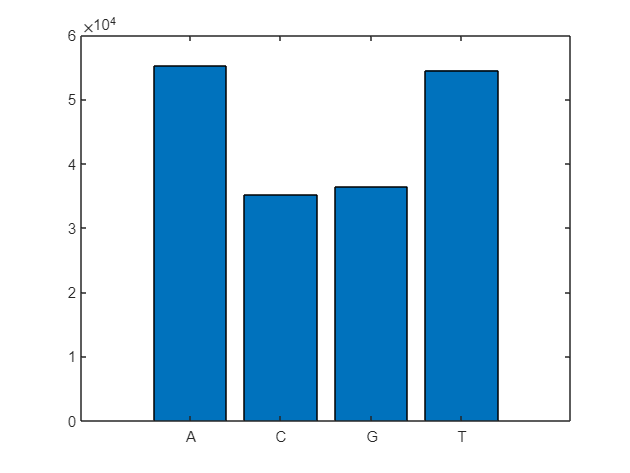

chart_freq = struct with fields:
    A: 55212
    C: 35226
    G: 36456
    T: 54559


figure(1)
chart_freq = basecount(beer053, 'CHART', 'bar')

     5. What does the function **ntdensity** show you about this sequence? 

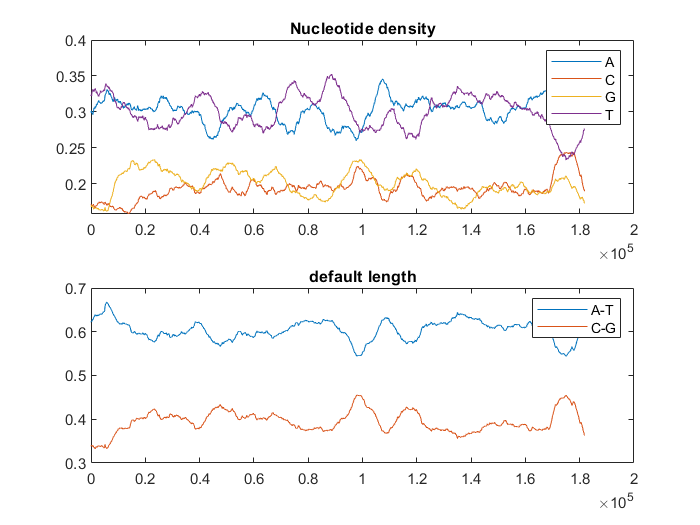

%   NTDENSITY(SEQ) plots the density of nucleotides A,T,C,G in sequence
%   SEQ.

ntdensity(beer053); title("default length");

        How does the window size affect this plot? 

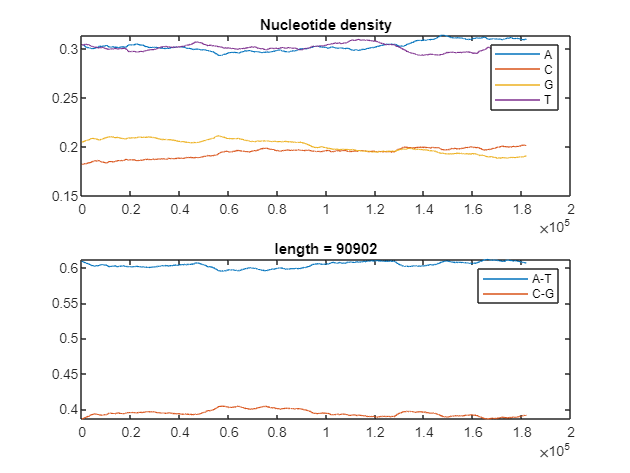

% smaller size gets frequencies more noisy

l1 = round(len/2);
l2 = round(len/20);
l3 = round(len/100);
figure(2);
subplot(3,1,1);  ntdensity(beer053,'window',l1);title("length = " + l1);

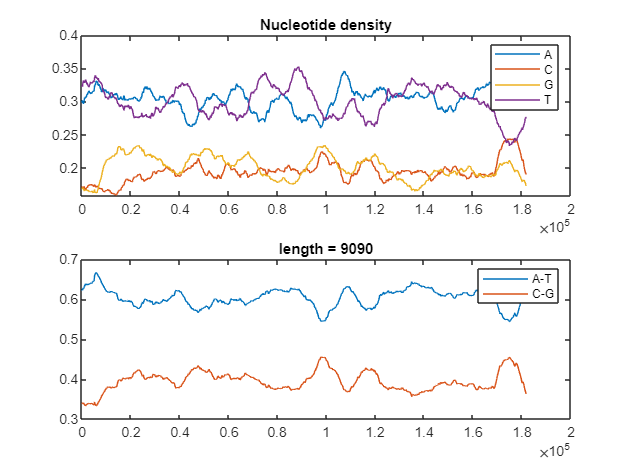

subplot(3,1,2);  ntdensity(beer053,'window',l2);title("length = " + l2);

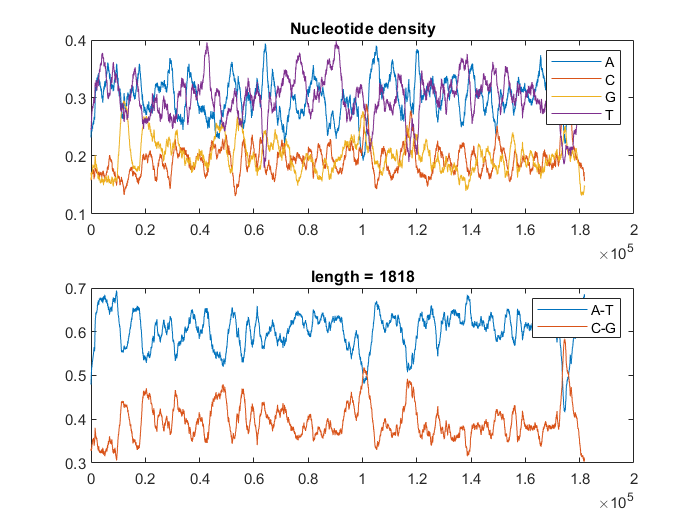

subplot(3,1,3);  ntdensity(beer053,'window',l3);title("length = " + l3); 

   6. Use the function **dimercount** to explore the dimers present in the sequence. 

%   DIMERCOUNT(SEQ) counts the number of occurrences of nucleotide dimers
%   in the sequence and returns these numbers in a structure with the
%   fields AA, AC, AG,..., GT, TT. 

[dimers, P] = dimercount(beer053);
P = reshape(P,[1,16]);
n = fieldnames(dimers);
names = cell2mat(n);

            a. Which dimer is the most common? 

%% TT is the most common

            b. If a C occurs, what is the most likely base next? 

%% T has highest chance of occurring after a C

        7. Given the frequencies of each individual base as counted in question 3, calculate which dimers occur unusually frequently/infrequently.  Can you say anything about the significance of these observations? 

% odds_matrix = [   
%     dimers.AA, dimers.AC, dimers.AG, dimers.AT;
%     dimers.CA, dimers.CC, dimers.CG, dimers.CT;
%     dimers.GA, dimers.GC, dimers.GG, dimers.GT;
%     dimers.TA, dimers.TC, dimers.TG, dimers.TT;
% ];


% loop through dimers and evaluate odds ratio
for k=1:length(names)           % for every dimer
    dimer = names(k,:)          % character array with symbols of bases
    dimer_freq = P(k);             % dimer observed frequency 
    p = 1;
    for base = 1:length(dimer)  % loop every base in the dimer
        b = dimer(base);        % single base
        fx= count_freq.(b)/len; % single base expected frequencies
        p = p * fx;             % product of expected frequencies
    end

    ratio = dimer_freq / p
end

dimer = 'AA'

ratio = 1.1359

dimer = 'AC'

ratio = 1.1219

dimer = 'AG'

ratio = 1.0643

dimer = 'AT'

ratio = 0.7538

dimer = 'CA'

ratio = 0.8989

dimer = 'CC'

ratio = 1.0799

dimer = 'CG'

ratio = 1.0150

dimer = 'CT'

ratio = 1.0538

dimer = 'GA'

ratio = 0.9947

dimer = 'GC'

ratio = 0.8005

dimer = 'GG'

ratio = 1.0417

dimer = 'GT'

ratio = 1.1187

dimer = 'TA'

ratio = 0.9443

dimer = 'TC'

ratio = 0.9711

dimer = 'TG'

ratio = 0.9103

dimer = 'TT'

ratio = 1.1480

    8. Use the function **codoncount** to count the codons starting in each reading frame. 

% count codons from each frame  
f1 = codoncount(beer053,'frame',1);
f2 = codoncount(beer053,'frame',2);
f3 = codoncount(beer053,'frame',3);
f4 = codoncount(beer053,'frame',1,'reverse', true);
f5 = codoncount(beer053,'frame',2,'reverse', true);
f6 = codoncount(beer053,'frame',3,'reverse', true);
f = fieldnames(f1);

            a. Which codon has the biggest variance in occurrences across the three reading frames? 

% evaluate all codons variance and find highest  
highest_variance = -0;
hv_codon = ["","",""];

for c = 1:numel(f)          % for each codon name
    codon = cell2mat(f(c)); % take symbols of codons
    
    
    % generate data with the 3 reading frames + reversed 3
    data = [f1.(codon) , f2.(codon) , f3.(codon), f4.(codon) , f5.(codon) , f6.(codon)];  
    
    
    % generate data with the 3 reading frames 
    % data = [f1.(codon) , f2.(codon) , f3.(codon)];  

    sigma = var(data);      % calculate variance
    if sigma > highest_variance   % update whenever highest variance is found
        highest_variance = sigma;
        hv_codon = codon;
    end
end

highest_variance, hv_codon

highest_variance = 1.2978e+04

hv_codon = 'TAA'

     9. **seqshoworfs **will display the open reading frames for a sequence and return information about them.  Count how many open reading frames there are in each reading frame.

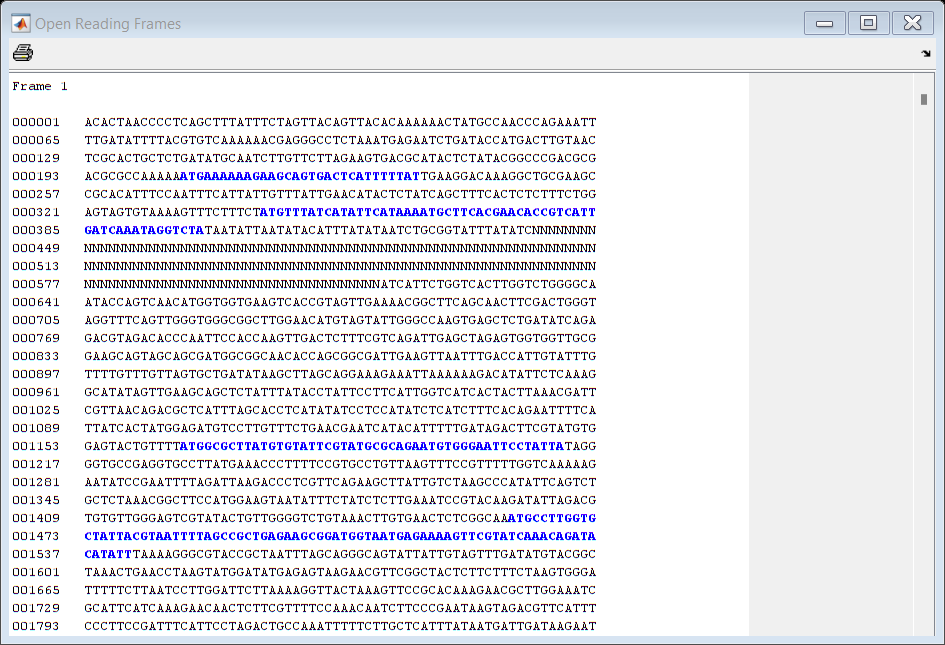

fs = 1×3 struct array with fields:
    Start
    Stop


fs = seqshoworfs(beer053, 'frames',[1 2 3])

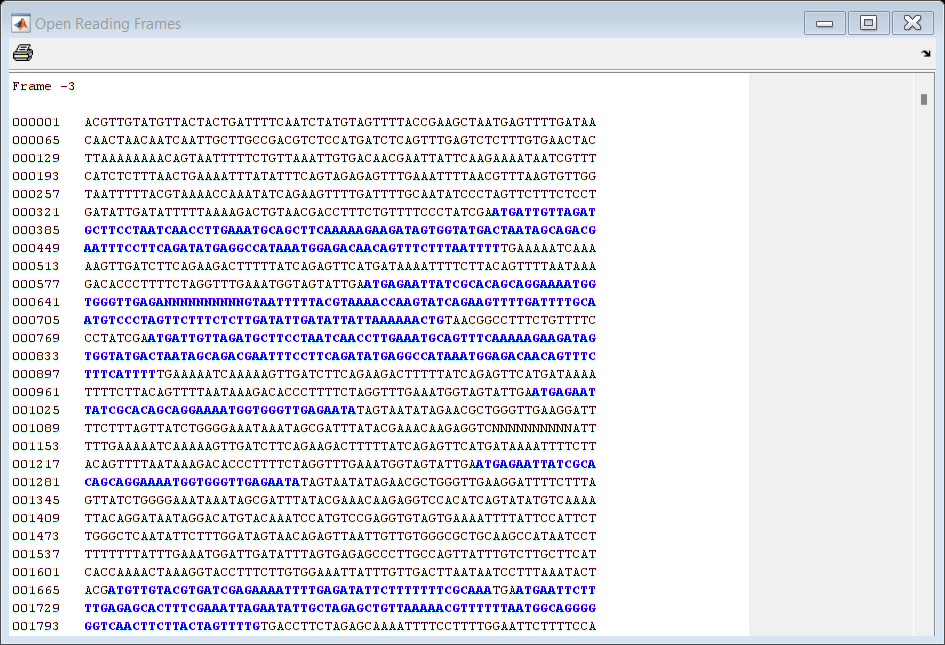

fsr = 1×6 struct array with fields:
    Start
    Stop



fsr = seqshoworfs(beer053, 'frames',[-3 -2 -1])

10. Make a histogram of the lengths of these ORFs. 

l1 = fs(1).Stop-fs(1).Start;
l2 = fs(2).Stop-fs(2).Start;
l3 = fs(3).Stop-fs(3).Start;
l1r = fsr(1).Stop-fsr(1).Start


l1r =

     []



l2r = fsr(2).Stop-fsr(2).Start


l2r =

     []



l3r = fsr(3).Stop-fsr(3).Start


l3r =

     []



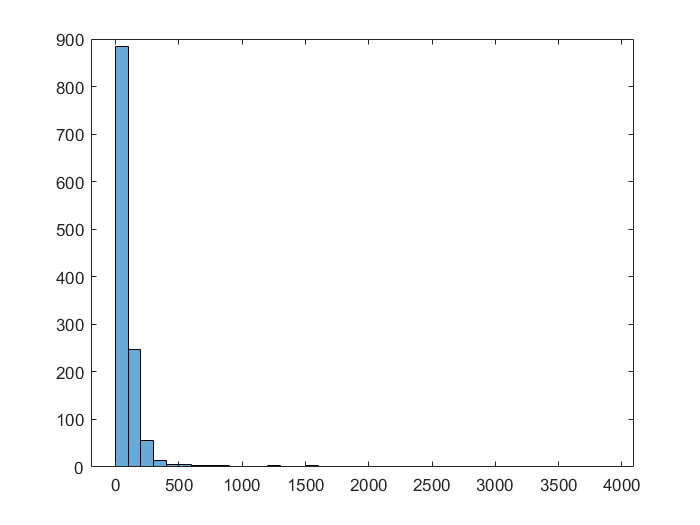

figure(8); histogram([l1 l2 l3])

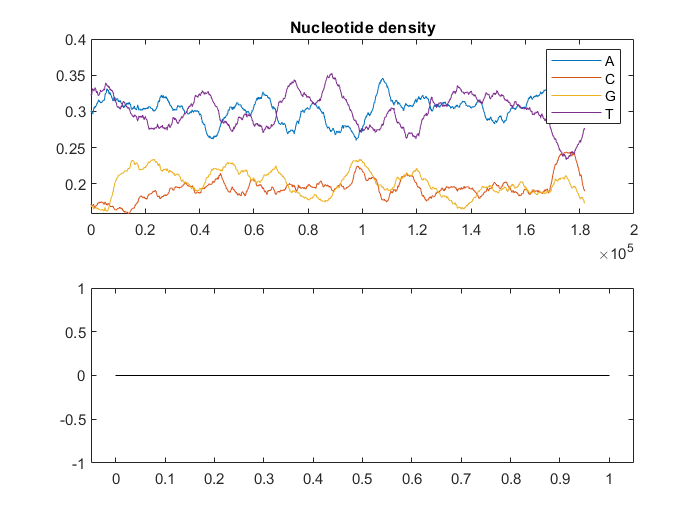

figure(9); histogram(l1r)

## Assignment: 

Like humans, Neanderthals had not only nuclear DNA, but also mitochondrial DNA in all their cells.  Like humans, the mitochondria of neanderthals contained 13 coding genes and 24 non-coding genes. The neanderthal mitochondrial genome has accession number 'NC_011137'.

- How does the number of genes stated above compare with the number of ORFs you find – explain your result. 

- Using what you have learnt above explore the neanderthal mitochondrial genome and find at least one *interesting* feature. Explain what you have found and what makes it interesting.

Make a new livescript with your working and explanations for this part and submit this file to the assignment on canvas.

Make sure to explain what you want to do, then put the code that does it, then finalise each section with an explanation of what you see in the results (for instance how do you interpret the plot, or the numbers you obtained).  Repeat this pattern for each major step/result in your report.  